clc
clear

**Kmeans**

a) Generate a 2D uncorrelated Gaussian distributed training dataset

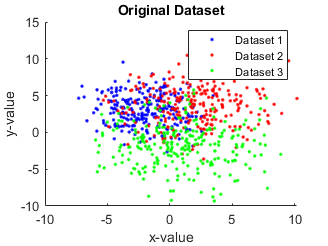

samples = 250;

%cluster 1 
mean1 = [-2; 3];
sd1 = 2;

%cluster 2
mean2 = [2; 4];
sd2 = 3;

%cluster 3
mean3 = [1; -2];
sd3 = 3.25;

dataset1 = sd1 * randn(2,samples) + repmat(mean1,1,samples);
dataset2 = sd2 * randn(2,samples) + repmat(mean2,1,samples);
dataset3 = sd3 * randn(2,samples) + repmat(mean3,1,samples);

%plot
hold on
plot(dataset1(1,:),dataset1(2,:),'b.')
plot(dataset2(1,:),dataset2(2,:),'r.')
plot(dataset3(1,:),dataset3(2,:),'g.')
xlabel('x-value')
ylabel('y-value')
title("Original Dataset")
legend('Dataset 1','Dataset 2','Dataset 3')
hold off

b) Concatenate the datasets into a single dataset and plot all the points

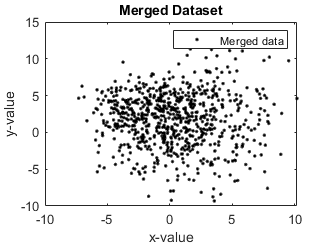

ConCluster = cat(2,dataset1,dataset2,dataset3);

plot(ConCluster(1,:),ConCluster(2,:),'black.')
title("Merged Dataset")
legend('Merged data')
xlabel('x-value')
ylabel('y-value')

c) Given the number of clusters as 3, implement Kmeans clustering from first principles

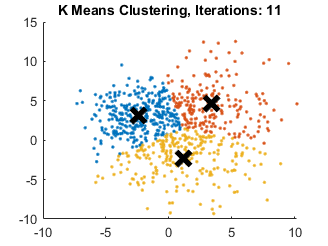

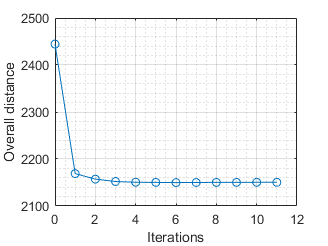

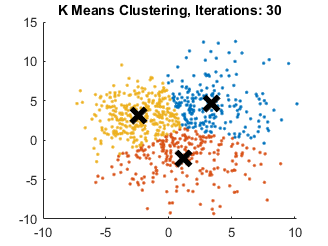

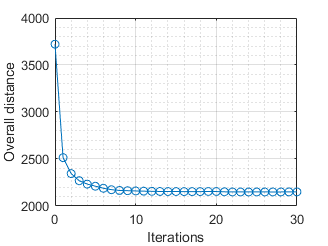

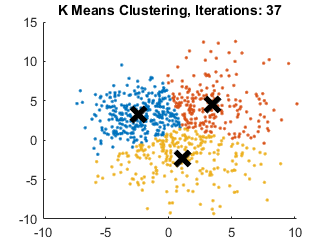

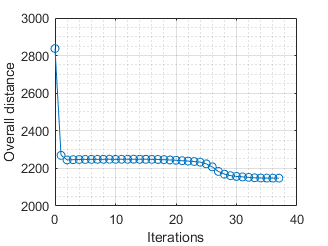

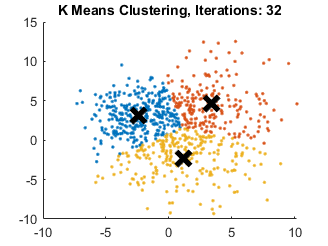

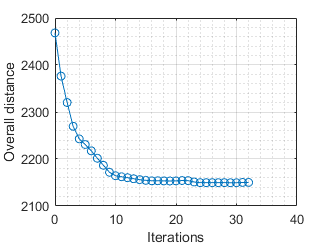

%select the number of clusters you want to identify in your data.
%this is the k in k-means clustering
k=3;
max_iterations = 20;

for j = 1:max_iterations
    done = false;
    iteration=0;

    centroidArray = [];
    newCentroidArray = [];
    distArray = [];
    clusterArray = [];

    %testing vars
    testTotalDistance=0;
    testTotalDistances = [];

    %step2 randomly select 3 destinct datapoints -> these are the initical clusters    
    for cen = 1:k
        r = (randi([1,size(ConCluster,2)],1));
        centroid = [ConCluster(1,r);ConCluster(2,r)];
        centroidArray = [centroidArray, centroid];
    end
    for i  = 1:size(ConCluster,2)
        distArray = [];
        %step 3 Measure the distances between the 1st point and the three initial
        %clusters

        %loop through centroidArray
        for cen = 1:k
            %calculate distance from each point
            %dist = sqrt((centroid1(1,1)-ConCluster(1,i))^2+(centroid1(2,1)-ConCluster(2,i))^2);
            dist = sqrt((centroidArray(1,cen)-ConCluster(1,i))^2+(centroidArray(2,cen)-ConCluster(2,i))^2);
            %save distance in distance array
            distArray = [distArray,dist];
        end
        %step 4 Assign the first point to the nearest cluster -> do the same for
        %the next point
        %-> measure the distances and assign the point to the nearest cluster
        for d = 1:k
            d;
            %check if first distance
            if d == 1
                %save distance for next iteration
                bestDist = distArray(d);
                bestCentNum = d;
            else
            %get distance
                %bestDist
                curDist = distArray(d);
            %compare with old distance
                if bestDist > curDist
                    %bestDist
                    bestDist = curDist;
                    bestCentNum = d;
                end
            end
        end
        testTotalDistance = testTotalDistance + bestDist;

        %assign point to nearest cluster
        [ConCluster(1,i);ConCluster(2,i);bestCentNum];
        clusterArray = [clusterArray, [ConCluster(1,i);ConCluster(2,i);bestCentNum]];
    end
    clusterArray;

    testTotalDistances = [testTotalDistances,[iteration;testTotalDistance]];
    
    while done==false
        iteration = iteration +1;
        testTotalDistance = 0;
        %step 5 calculate the mean of each cluster
        %repeat what just did (measure and cluster) using the mean values
        %sum of rows
        newCentroidArray = [];
        %calculate mean of each cluster
        for cen = 1:k
            %get cluster(cen)
            clustIdxs = find(clusterArray(3,:)==cen);
            clust = clusterArray(:,clustIdxs);
            %calc mean of that cluster and add to newClusterArray
            clustSize = size(clust,2);
            newCentroidArray = [newCentroidArray,[(sum(clust(1,:)))/clustSize;(sum(clust(2,:)))/clustSize]];
        end
        clusterArray = [];
        newCentroidArray;
        for i  = 1:size(ConCluster,2)                    
            %set reset distArray
            distArray = [];
            %loop through centroidArray
            for cen = 1:k
                %calculate distance from each point
                dist = sqrt((newCentroidArray(1,cen)-ConCluster(1,i))^2+(newCentroidArray(2,cen)-ConCluster(2,i))^2);
                %save distance in distance array
                distArray = [distArray,dist];
            end
            for d = 1:k
                %check if first distance
                if d == 1
                    %save distance for next iteration
                    bestDist = distArray(d);
                    bestCentNum = d;
                else
                    %get distance
                    curDist = distArray(d);
                    %compare with old distance
                    if bestDist > curDist
                        %bestDist
                        bestDist = curDist;
                        bestCentNum = d;
                    end
                end
            end
            testTotalDistance = testTotalDistance + bestDist;
            %assign point to nearest cluster
            clusterArray = [clusterArray, [ConCluster(1,i);ConCluster(2,i);bestCentNum]];

        end
        %clusterArray
        testTotalDistances = [testTotalDistances,[iteration;testTotalDistance]];  
        testTotalDistance=0;

        %if clustering does not change during iteration then k-means is complete
        if (centroidArray == newCentroidArray)% finish !!!!!!!!!!!!!
            %stop 
            iteration;
            done=true;
            figure
            hold on
            for cen = 1:k
                %get cluster(cen)
                clustIdxs = find(clusterArray(3,:)==cen);
                clust = clusterArray(:,clustIdxs);
                %plot on graph
                plot(clust(1,:),clust(2,:),'.')
            end
            %centroidArray
            for cen = 1:k
                newCentroidArray;
                plot(newCentroidArray(1,cen),newCentroidArray(2,cen),'black x','MarkerSize',15,'linewidth',4)
            end
            titleName = append('K Means Clustering, Iterations: ',int2str(iteration));
            title(titleName)
            hold off

            %plot distances and iterations
            figure
            title('Test Overall distances vs. number of iterations')
            xlabel('Overall distances')
            ylabel('Iterations')
            plot(testTotalDistances(1,:),testTotalDistances(2,:),'o-')
            grid on
            grid minor
            xlabel('Iterations')
            ylabel('Overall distance')
            testTotalDistances = [];

            
        else
            %continue
            done = false;

            centroidArray = newCentroidArray;
            %newCentroidArray = [];
            if iteration == 100%Give up after 100 iterations
                done = true;
            end
        end
    end
        
end



%can assess the quality of the clustering by adding up the variation within
%each cluster

%keep track of these clusters and their total varience and do the whole
%thing over with different starting points


d) If the number of clusters is unknown, explain and find out (via matlab code) the best number of clusters.

%Elbow plot
%calculate how bad it is with total variation -> 
%calculate variation
%calcVariation([6,9,14,10,5,8,11])
%k = 3;
%l = temp(ConCluster,k)

function [variation] = calcVariation(a)
    %a = [6,9,14,10,5,8,11];
    s = size(a,2);
    b = 0;
    for i = 1:size(a,2)
        b = b + ((a(i)-mean(a))^2);
    end
    %variation = ((a[i]-mean(a[i]))^2)
    variation = b/size(a,2)
end

e) From  your  observation  and  analysis,  what  are  the  limitations  or  drawbacks  of  Kmeans clustering?  

%